# **Mortality Prediction of COVID-19 Patients Using Logistic Regression and Random Forest**  

**Behzad Javaheri**

**Department of Computer Science, City University of London UK  **

# **1. Data preparation and preprocessing**

The original dataset is available from Github within an R file: [https://github.com/alberto-mateos-mo/covid19mx/blob/master/data-raw/covid19mx_data.R](https://github.com/alberto-mateos-mo/covid19mx/blob/master/data-raw/covid19mx_data.R)

Using R, the data extracted and exported into a CSV file (350 mb) which can be downloaded from: 

Once downloaded it needs to be stored in the same folder as this MATLAB file. Data import can subsequently be imported.

## 1.1 Data Import

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Importing the dataset and visualizing the table
data = readtable("covidmx.csv","TreatAsEmpty",[".","NA"]);

After import, the dataset needs to be preprocessed. Appropriate commenting provided above or next to each step.

## 1.2 Data preprocessing

### 1.2.1 Initial steps

#### 1.2.1.1 Change column names

% Original variable names are in Spanish. Here these names are changed to English achieved by using the VariableNames property of MATLAB table: 

cleanedData_1 = data; % Copying the imported file, in case that I need to return to it
cleanedData_1.Properties.VariableNames([1:39]) = [" ", "Date_of_update", "Record_ID", "Patient_type", "Treatment_hospital", "State_of_hospital", "Gender",...
                                "State_of_birth", "State_of_residence", "Town_of_residence", "Hospitalisation", "Admission_date",...
                               "Date_of_first symptom", "Deceased", "Intubation", "Pneumonia", "Age", "Is_Mexican", "Pregnancy", "Native_language",...
                               "Indigenous", "Diabetes", "COPD", "Asthma", "Immunosuppression", "Hypertension", "Other_comorbidities", "Cardiovascular_disease",...
                               "Obesity", "CKD", "Smoker", "Contact_with_positive", "Sample_taken", "Laboratory", "Test_result", "Is_Migrant", "Nationality",...
                               "Country_of_origin", "ICU"]; %Changing variable names to English

#### 1.2.1.2 Removing irrelevant variables and replacing missing values with NaN

% Deleting variables which are not relevant to the question posed in this study.
cleanedData_2= removevars(cleanedData_1,[" ", "Date_of_update", "Record_ID","Patient_type", "Treatment_hospital", "State_of_hospital","State_of_birth", ...
                                         "State_of_residence", "Town_of_residence", "Hospitalisation", "Is_Mexican", "Native_language","Indigenous", "Is_Migrant", ...
                                         "Nationality","Country_of_origin","Admission_date","Date_of_first symptom","Sample_taken",...
                                         "Contact_with_positive", "Laboratory", "Test_result"]);
                                    
% Replacing values that indicate missing values with "NaN". In this process variable "Age" is excluded as there are some valid numbers of 99, 97, 98 in this variable.                                    
cleanedData_2 = standardizeMissing(cleanedData_2,[99,97,98],'DataVariables',["Gender", "Intubation", "Pneumonia", "Pregnancy","Diabetes", "COPD",...
                                                                             "Asthma", "Immunosuppression", "Hypertension", "Other_comorbidities",...
                                                                             "Cardiovascular_disease","Obesity", "CKD", "Smoker", "ICU"]);

#### 1.2.1.3 Modifying "Pregnancy" variable

% Missing values in the "Pregnancy" variable relate to "males". Removing missing values in this columns will result in deletion of males from the dataset.
% To prevent this, I will assign pregnancy values for males to "3". Females have 1 and 2 for pregnancy and no pregnancy respectively. 
cleanedData_2.Pregnancy(isnan(cleanedData_2.Pregnancy)) = 3;
toDelete = cleanedData_2.Gender == 1 & cleanedData_2.Pregnancy == 3;
cleanedData_2(toDelete,:) = [];

#### 1.2.1.4 Modifying "Deceased" column

% For the outcome column, presence of a date suggests mortality and '9999-99-99' as survival. here I will assign labels accordingly. 
cleanedData_2.Deceased(strcmpi(cleanedData_2.Deceased,'9999-99-99')) = {0};
cleanedData_2.Deceased = string(cleanedData_2.Deceased);
cleanedData_2.Deceased = double(cleanedData_2.Deceased);
cleanedData_2.Deceased(isnan(cleanedData_2.Deceased)) = 1;

### 1.2.2 Addressing missing values

#### 1.2.2.1 Testing for missing values

% Test for missing values
ismissing(cleanedData_2);

#### 1.2.2.2 Visualisation of missing values

% Visualisation of missing values will help to decide their removal
variables = cleanedData_2.Properties.VariableNames;
figure
imagesc(ismissing(cleanedData_2))
ax = gca;
ax.XTick = 1:17;
ax.XTickLabel = variables;
ax.XTickLabelRotation = 90;
title('Missing values in the COVID-19 dataset')

#### 1.2.2.3 Removing variable with significant amount of missing values

% Visualising above heatmap indicate significant amount of missing values
% in "ICU" and "Intubation" variables. These can be dealt with by keeping
% these 2 variables and removing values which will result in significant
% reduction in dataset. Alternatively, removal of these 2 variables
% addresses missing values without detrimental effect on the dataset.
cleanedData_3= removevars(cleanedData_2,["ICU","Intubation"]);

#### 1.2.2.4 Removing some minor missing values and visualisation to confirm that data is free of missing values

% removing missing values from dataset. To remove rows from a table which contain an undefined or missing value, you can use the rmmissing function.
cleanedData_3 = rmmissing(cleanedData_3);

% Visualising the data after removal of missing values
variables = cleanedData_3.Properties.VariableNames;  % extract column names
figure
imagesc(ismissing(cleanedData_3))
ax = gca;
ax.XTick = 1:17;
ax.XTickLabel = variables;
ax.XTickLabelRotation = 90;
title('Successful removal of missing values in the COVID-19 dataset')

### 1.2.3 Additional steps

#### 1.2.3.1 Reordering columns so that relevant columns are next to each other.

% Reordering variables so that closely connected variables are put closer
cleanedData_4 = movevars(cleanedData_3, "Deceased", "After", "Smoker");
cleanedData_4 = movevars(cleanedData_4, "Other_comorbidities", "After", "Smoker");
cleanedData_4 = movevars(cleanedData_4, "Age", "Before", "Gender");
cleanedData_4 = movevars(cleanedData_4, "Pregnancy", "After", "Gender");
cleanedData_4 = movevars(cleanedData_4, "Pneumonia", "Before", "Deceased");
cleanedData_4 = movevars(cleanedData_4, "Obesity", "before", "Diabetes");
dataF = cleanedData_4;

%clearvars -except dataF

# **2. Descriptive statistics and visualisation**

## 2.1 Basic descriptive statistics

% In this step, some basic information about the data extracted and data
% visualised.

summary(dataF) % Calculating descriptive statistics

statarray = grpstats(dataF,["Deceased"], "mean","DataVars",["Age"]) % Calculating group statistics by outcome variable (Deceased).
probplot('normal',dataF.Age)
%calculating basic statistics according to a grouping variable using groupsummary function
stats3 = groupsummary(dataF,"Deceased","sum")

## 2.2 Correlation coefficient

In this step correlation between variables is explored and visualised using a heatmap.

cleanedData_3= removevars(cleanedData_2,["ICU","Intubation"]);

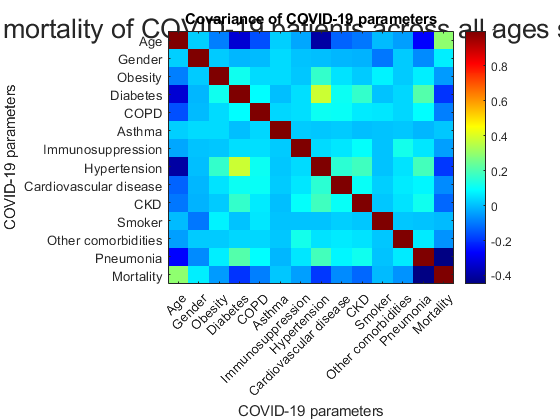

dataF_covmat = table2array(dataF);
covmat = corrcoef(dataF_covmat);
imagesc(covmat)
ax = gca;
colormap(jet);
colorbar;
xlabel('COVID-19 parameters');
ylabel('COVID-19 parameters');
title('Covariance of COVID-19 parameters');
N=15;
labelNames = {'Age', 'Gender', 'Obesity', 'Diabetes', 'COPD','Asthma', 'Immunosuppression', 'Hypertension',... 
    'Cardiovascular disease', 'CKD', 'Smoker','Other comorbidities', 'Pneumonia', "Mortality"};
set(gca,'XTick',1:N);
set(gca,'YTick',1:N);
set(gca,'XTickLabel',labelNames);
set(gca,'XTickLabelRotation',45)
set(gca,'YTickLabel',labelNames);

## 2.3 Data distribution by histograms

In this step, a series of histogram is plotted to investigate data distribution that may later on help with optimising data for better model performance

% Distribution of survival and mortality of all COVID-19 patients across all ages
figure
h = tiledlayout("flow");
title(h,"Survival and mortality distribution of COVID-19 patients across all ages", 'fontsize',20)
ax1 = nexttile;
histogram(ax1,dataF.Age (dataF.Deceased == 0),'FaceColor','#00AFBB' )
hold on
histogram(dataF.Age (dataF.Deceased == 1),'FaceColor','#AB6857' )
hold off
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
% Distribution of survival and mortality of COVID-19 male and female patients across all ages
nbins = 150;
figure
h = tiledlayout("flow");
title(h,"Survival and mortality distribution of COVID-19 male and female patients across all ages", 'fontsize',20)
nexttile
x1 = dataF.Age(dataF.Deceased == 1 & dataF.Gender == 2);
h1 = histogram(x1, nbins, 'FaceColor','red' );
hold on
ylim([1 30000]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Males')
x2 = dataF.Age(dataF.Deceased == 0 & dataF.Gender == 2);
h2 = histogram(x2,'FaceColor','#00AFBB' );
ylim([1 30000]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Males')
hold off
legend({'Mortality' 'Survival'})

nexttile
x3 = dataF.Age(dataF.Deceased == 1 & dataF.Gender == 1);
h3 = histogram(x3, nbins,'FaceColor','red' );
hold on
ylim([1 30000]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Females')
x4 = dataF.Age(dataF.Deceased == 0 & dataF.Gender == 1);
h4 = histogram(x4, 'FaceColor','#00AFBB' );
ylim([1 30000]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Females')
hold off
legend({'Mortality' 'Survival'})
figure
nbins = 110;
h = tiledlayout("flow");
title(h,"Mortality distribution of COVID-19 male and female patients across all ages", 'fontsize',20)
nexttile
x1 = dataF.Age(dataF.Deceased == 1 & dataF.Gender == 2);
histogram(x1, nbins, 'FaceColor','red' );
ylim([1 2500]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Males')

nexttile
x1 = dataF.Age(dataF.Deceased == 1 & dataF.Gender == 1);
histogram(x1, nbins, 'FaceColor','red' );
ylim([1 2500]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Females')
% Distribution of survival of COVID-19 patients across all ages separated by smoking status
figure
h = tiledlayout("flow");
title(h,"Distribution of survival and mortality of COVID-19 patients across all ages separated by smoking status", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.Smoker == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Smoker == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Non-smoker')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.Smoker == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Smoker == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Smoker')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by obesity
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by obesity", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.Obesity == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Obesity == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No obesity')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.Obesity == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Obesity == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Obesity')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by Asthma
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by Asthma", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.Asthma == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Asthma == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No asthma')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.Asthma == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Asthma == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Asthma')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by diabetes
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by diabetes", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.Diabetes == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Diabetes == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No diabetes')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.Diabetes == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Diabetes == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Diabetes')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by immunosuppression
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by immunosuppression", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.Immunosuppression == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Immunosuppression == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No immunosuppression')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.Immunosuppression == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Immunosuppression == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Immunosuppression')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by COPD
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by COPD", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.COPD == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.COPD == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No COPD')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.COPD == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.COPD == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('COPD')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by Cardiovascular disease
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by Cardiovascular disease", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.Cardiovascular_disease == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Cardiovascular_disease == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No cardiovascular disease')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.Cardiovascular_disease == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Cardiovascular_disease == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Cardiovascular disease')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by CKD
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by CKD", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.CKD == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.CKD == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No CKD')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.CKD == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.CKD == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('CKD')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by Other comorbidities
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by Other comorbidities", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.Other_comorbidities == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Other_comorbidities == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No other comorbidities')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.Other_comorbidities == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Other_comorbidities == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Comorbidities')

% Distribution of survival and mortality of COVID-19 patients across all ages separated by Pneumonia
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by Pneumonia", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF.Age(dataF.Deceased == 0 & dataF.Pneumonia == 2), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Pneumonia == 2), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('No Pneumonia')
ax2 = nexttile;
histogram(ax2, dataF.Age(dataF.Deceased == 0 & dataF.Pneumonia == 1), 'FaceColor','#00AFBB' );
hold on
histogram(dataF.Age(dataF.Deceased == 1 & dataF.Pneumonia == 1), 'FaceColor','#AB6857' );
hold off
ylim([0 60000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Pneumonia')

clearvars -except dataF
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

writetable(dataF,'myData.csv','Delimiter',',','QuoteStrings',true);
type 'myData.csv';

# **3. Building, optimising and testing two models: Logistic Regression and Random Forest**

## 3.1 Logistic regression

### 3.1.1 Dividing the dataset into training and testting 

Data in this table except for "Age" and "Deceased" are in the form of 1 (true) and 2 (false). For "Deceased" column these are 0 (false) and 1 (true).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[m,n] = size(dataF) ;
P = 0.80; % The size of the training dataset is set to 80% of total size of dataset

rng('default'); % To prevent randperm function to draw random numbers after each run, "rng" is used. This is to ensure reproducibility 

% Create a series of index to randomly split the data into 80% training and 20% testing.
idx = randperm(m); % Generate a vector of random permutation of all data: m is the size of the datapoints
trainingData = dataF(idx(1:round(P*m)),:); % Defining the training features of the datasets corresponding to the randomly shuffled vector
testingData = dataF(idx(round(P*m)+1:end),:);  % Defining the testing features of the datasets corresponding to the randomly shuffled vector

### 3.1.2 First group of logistic regression models (LR_Mdl)

% Defining predictors and output response
xtrainNames = {'Age', 'Gender', 'Pregnancy', 'Obesity', 'Diabetes', 'COPD', 'Asthma', 'Immunosuppression', 'Hypertension',... 
    'Cardiovascular_disease', 'CKD', 'Smoker','Other_comorbidities', 'Pneumonia'};
xTrain = trainingData(:, xtrainNames); % Predictors
xTrain = table2array(xTrain);
yTrain = double(trainingData.Deceased); % Output

thresholdmdl = 0.5; % Define a threshold for classification
numSamples = length(yTrain); % Number of samples
numBoots = 30; % Number of bootstrap samples
mdl_boot  = cell(numBoots,1); % Pre-allocate memory for the resampled fit values
predBoot_Mdl1 = zeros(numSamples,1);
[Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time] = deal(zeros(numBoots,1)); % Container for storing performance measure obtained  during the loop
Time = zeros(numBoots,1);

% Resample, iterate and model each instance of the resampled data
for i = 1:numBoots
    resampling_ix = ceil(numSamples*rand(1,numSamples));
    resampled_x = xTrain(resampling_ix,:);
    resampled_y = yTrain(resampling_ix);

    tic % Start recording time
    mdl_boot{i}= fitglm(resampled_x,resampled_y,'Distribution', 'binomial', 'link', 'logit'); % Fitting logistic regression
    predBoot_Mdl1(:,i) = predict(mdl_boot{i},resampled_x) >= thresholdmdl; % Prediction using the the model built above   
    
    % Calculating measures of performance
    TP(i) = sum((predBoot_Mdl1(:,i) == 0) & (resampled_y == 0)); % True positive
    FP(i) = sum((predBoot_Mdl1(:,i) == 1) & (resampled_y == 0)); % False positive
    FN(i) = sum((predBoot_Mdl1(:,i) == 0) & (resampled_y == 1)); % False negative
    TN(i) = sum((predBoot_Mdl1(:,i) == 1) & (resampled_y == 1)); % True negative
    Precision(i) = TP(i)/ (TP(i)+FP(i)); % ratio of correct predictions for the positive class out of total possible positives.
    Recall(i) = TP(i)/ (TP(i)+FN(i)); % ratio of correct positive predictions.
    Specificity(i) = TN(i)/ (FP(i)+TN(i)); % Specificity
    BM(i) = Recall(i)+Specificity(i)-1; % Bookmaker informedness
    FPR(i) = FP(i)/ (TN(i)+FP(i)); % False positive rate
    FNR(i) = FN(i)/ (FN(i)+TP(i)); % False negative rate
    FOR(i) = FN(i)/ (FN(i)+TN(i)); % False ommission rate
    NPV(i) = TN(i)/ (TN(i)+FN(i)); % Negative predictor value
    FDR(i) = FP(i)/ (FP(i)+TP(i)); % False discovery rate
    MCC(i) = (TP(i)*TN(i)-FP(i)*FN(i))/sqrt((TP(i)+FP(i))*(TP(i)+FN(i))*(TN(i)+FP(i))*(TN(i)+FN(i))); % Matthews correlation coefficient
    MK(i) = Precision(i)+NPV(i)-1; % Markedness 
    F1(i) = (2*Precision(i)*Recall(i))/ (Precision(i)+Recall(i)); % average (weighted) Precision and Recall.
    F2(i) = (5*Precision(i)*Recall(i)/ ((4*Precision(i)) + Recall(i))); % similar to F1 but less weight on Precision, more weight on Recall.
    Accuracy(i) = (TP(i)+TN(i))./(TP(i)+FP(i)+TN(i)+FN(i))*100; % Accuracy
    scores = mdl_boot{i}.Fitted.Probability;
    [X,Y,T,AUC(i)] = perfcurve(resampled_y,scores,'1');
    AUC(i); % Area under the curve
    Time(i) = toc; % End recording time
end

% Creating a table of measures of performance
LR_MdlPerformance = table(Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time,...
    'RowNames',{'Model 1' 'Model 2' 'Model 3' 'Model 4' 'Model 5' 'Model 6' 'Model 7' 'Model 8' 'Model 9' 'Model 10' ...
                'Model 11' 'Model 12' 'Model 13' 'Model 14' 'Model 15' 'Model 16' 'Model 17' 'Model 18' 'Model 19' 'Model 20' ...
                'Model 21' 'Model 22' 'Model 23' 'Model 24' 'Model 25' 'Model 26' 'Model 27' 'Model 28' 'Model 29' 'Model 30'})
% Visualising in 4D the performance of above model using scatter3 and stacked plot
figure
scatter3(LR_MdlPerformance.Precision, LR_MdlPerformance.Recall, LR_MdlPerformance.Specificity, 100, LR_MdlPerformance.Accuracy, 'filled')
set(gca,'color',"#ecf0f1")
title('Performance measures of 30 logistic regression models', 'FontSize', 20)
xlabel('Precision', 'FontSize', 20)
ylabel('Recall', 'FontSize', 20)
zlabel('Specificity', 'FontSize', 20)
colormap(jet)
hcb = colorbar('Location', 'EastOutside', 'FontSize', 20);
hcb.Title.String = "Accuracy";

xplot = [0:1:29]; % stacked plot to visualise the remainder measures of performance to aid selecting the best performing model
stackedplot(LR_MdlPerformance,["BM","FPR","FNR","FOR","NPV","FDR","MCC","MK","F1","F2","AUC","Time"]);

### 3.1.3 Validating the selected LR model on the entire training dataset

% Selecting the highest performing model
LR_Index = find(LR_MdlPerformance.Specificity == max(LR_MdlPerformance.Specificity(:))); % Finding the best performing model which has the highest specificity
LR_Mdl = mdl_boot(LR_Index,1); % The index of first logistic regression best performing model 
LR_Mdl = LR_Mdl{:,:}; % Finding and saving the best performing model

tic % Start recording execution time
thresholdmdl = 0.5; % Define a threshold for classification
LR_Mdl_pred = predict(LR_Mdl,xTrain) >= thresholdmdl; % Prediction on the entire training dataset

% Calculating performance measures
TP = sum((LR_Mdl_pred == 0) & (yTrain == 0)); % True positive
FP = sum((LR_Mdl_pred == 1) & (yTrain == 0)); % False Positive
FN = sum((LR_Mdl_pred == 0) & (yTrain == 1)); % False negative
TN = sum((LR_Mdl_pred == 1) & (yTrain == 1)); % True Negative
% Using TP, FP, FN and TN we will calculate measures of performance
Precision = TP/ (TP+FP); % ratio of correct predictions for the positive class out of total possible positives.
Recall = TP/ (TP+FN); % ratio of correct positive predictions.
Specificity = TN/ (FP+TN); % Specificity
BM = Recall+Specificity-1; % Bookmaker informedness
FPR = FP/ (TN+FP); % False positive rate
FNR = FN/ (FN+TP); % False negative rate
FOR = FN/ (FN+TN); % False ommission rate
NPV = TN/ (TN+FN); % Negative predictor value
FDR = FP/ (FP+TP); % False discovery rate
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN)); % Matthews correlation coefficient
MK = Precision+NPV-1; % Markedness 
F1 = (2*Precision*Recall)/ (Precision+Recall); % average (weighted) Precision and Recall.
F2 = (5*Precision*Recall/ ((4*Precision) + Recall)); % similar to F1 but less weight on Precision, more weight on Recall.
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100; % Accuracy 
[scores] = predict(LR_Mdl,xTrain);
[X,Y,T,AUC] = perfcurve(yTrain,scores,'1');
AUC;
Time = toc; % Stop recording time

% Appending the performance of the model on the entire training dataset to a table
LR_MdlHighestPerformance = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'Best-performing LR Mdl1'}) % Creating a table of performance for the best performing model

### 3.1.5 Visualising the performance of this initial LR model

% Plotting the performance of the model: confusion chart, ROC curve and plot of residuals
figure
tiledlayout('flow');
nexttile
Confmat_LRMdl1 = confusionchart(yTrain,double(LR_Mdl_pred),'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_LRMdl1,["1","0"]);
Confmat_LRMdl1.Normalization = 'absolute'; 
title("Confusion chart");
nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve')
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')
nexttile
plotResiduals(LR_Mdl,'probability')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### 3.1.6 Optimisation to achieve better performance

#### 3.1.6.1 Visualising age-related data imbalance

Here, the age-related imbalance will be addressed confining the analysis to an age range to avoid imbalance.  Additionally and according to the literature COVID-19 death is significantly low below the age of 30, therefore a model to predict mortality does not need inclusion of ages below 30 as very high survival imbalances the dataset. An example: [https://www.thelancet.com/journals/landia/article/PIIS2213-8587(20)30272-2/fulltext](https://www.thelancet.com/journals/landia/article/PIIS2213-8587(20)30272-2/fulltext)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% First we will visualise whether there is an imbalance, calculate and plot
% the proportion of survival and mortality on the histograms
DataF_OP1 = dataF;
figure
h = tiledlayout("flow");
title(h,"Distribution of COVID-19 survival and mortality for both sexes across all ages", 'fontsize',20)
nexttile
x1 = DataF_OP1.Age(DataF_OP1.Deceased == 1 & DataF_OP1.Gender == 2);
histogram(x1, 'FaceColor','red' );
under30 = (sum(x1<30)/numel(x1))* 100;
xline(30,'--',{'Under 30','2.4% mortality'});
ylim([1 30000]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Mortality (Males)')
nexttile
x2 = DataF_OP1.Age(DataF_OP1.Deceased == 0 & DataF_OP1.Gender == 2);
histogram(x2, 'FaceColor','#00AFBB' );
ylim([1 30000]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Survival (Males)')
under30 = (sum(x2<30)/numel(x2))* 100; % Calculating the proportion of survival below 30
line = xline(30,'--',{'Under 30','26.7% Survival'}); % Plotting a vertical line with above information

nexttile
x1 = DataF_OP1.Age(DataF_OP1.Deceased == 1 & DataF_OP1.Gender == 1);
histogram(x1, 'FaceColor','red' );
under30 = (sum(x1<30)/numel(x1))* 100;
xline(30,'--',{'Under 30','2.8% mortality'});
ylim([1 30000]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Mortality (Females)')
nexttile
x2 = DataF_OP1.Age(DataF_OP1.Deceased == 0 & DataF_OP1.Gender == 1);
histogram(x2, 'FaceColor','#00AFBB' );
ylim([1 30000]);
xlim([1 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Survival (Females)')
under30 = (sum(x2<30)/numel(x2))* 100; % Calculating the proportion of mortality below 30
line = xline(30,'--',{'Under 30','27% Survival'}); % Plotting a vertical line with above information

#### 3.1.6.2 Removing data for under 30s

% Removing data related to under 30s
toDelete = DataF_OP1.Age < 30;
DataF_OP1(toDelete,:) = []

#### 3.1.6.3 Visualising sex-related data imbalance

figure
h = tiledlayout("flow");
title(h,"Distribution of COVID-19 male and female mortality across all ages", 'fontsize',20)
nexttile
x1 = DataF_OP1.Age(DataF_OP1.Deceased == 1 & DataF_OP1.Gender == 2);
histogram(x1, 'FaceColor','red' );
ylim([1 2500]);
xlim([30 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Males')

nexttile
x1 = DataF_OP1.Age(DataF_OP1.Deceased == 1 & DataF_OP1.Gender == 1);
histogram(x1, 'FaceColor','red' );
ylim([1 2500]);
xlim([30 100]);
xlabel('Age (in years)')
ylabel('Counts')
title('Females')

#### 3.1.6.4 Addressing sex-related data imbalance by splitting the dataset based on sex

%Males
dataF_Male_OP2 = DataF_OP1; 
toDelete = dataF_Male_OP2.Gender < 2; % 2 is the label for males, therefore smaller than 2 will select females for deletion
dataF_Male_OP2(toDelete,:) = [];
dataF_Male_OP2= removevars(dataF_Male_OP2,["Gender","Pregnancy"]); % Deleting redundant columns for males after splitting

%Females
dataF_Female_OP2 = DataF_OP1; 
toDelete = dataF_Female_OP2.Gender > 1; % 1 is the label for males, therefore greater than 1 will select males for deletion
dataF_Female_OP2(toDelete,:) = [];

dataF_Female_OP2= removevars(dataF_Female_OP2,["Gender"]); % Deleting redundant columns for females


#### 3.1.6.5 Addressing class-related data imbalance

#### 3.1.6.5.1 Visualising class-related data imbalance for both male and female datasets

figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients across all ages separated by gender", 'fontsize',20)
ax1 = nexttile; % Males
histogram(ax1, dataF_Male_OP2.Age(dataF_Male_OP2.Deceased == 0), 'FaceColor','blue' );
hold on
histogram(dataF_Male_OP2.Age(dataF_Male_OP2.Deceased == 1), 'FaceColor','red' );
hold off
ylim([1 30000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Males')
ax2 = nexttile; % Females
histogram(ax2, dataF_Female_OP2.Age(dataF_Female_OP2.Deceased == 0) ,'FaceColor','#7293CB');
hold on
histogram(dataF_Female_OP2.Age(dataF_Female_OP2.Deceased == 1), 'FaceColor','#D35E60');
hold off
ylim([1 30000]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Females')

#### 3.1.6.5.2 Addressing class-related data imbalance by undersampling majority (surival) class

% The significant imbalance in the number of survival and mortality can be
% addressed by equalising the number of both classes. One way to achieve
% this is by random removal of excessive number from the majority class.
% This implementation is inspired by the following discussion
% https://uk.mathworks.com/matlabcentral/answers/343780-randomly-selecting-rows-based-on-a-given-criteria of cases in the majority class

% Males
dataF_Male_OP3 = dataF_Male_OP2;
numDeceased_Male = find(dataF_Male_OP3.Deceased == 1);
numSurvived_Male = find(dataF_Male_OP3.Deceased == 0);
NumberToDelete_Male = length(numSurvived_Male) - length(numDeceased_Male); %Finding the difference in the number of excessive cases in the majority class
Idx_Male = randperm(length(numSurvived_Male), NumberToDelete_Male);        % Generating random indices (no repeats) to match the number of excessive cases
SelectToKeep_Male = true(size(dataF_Male_OP3,1),1); % Minority class is retained
SelectToKeep_Male(numSurvived_Male(Idx_Male)) = false;
dataF_Male_OP3 = dataF_Male_OP3(SelectToKeep_Male,:); 

%Females
dataF_Female_OP3 = dataF_Female_OP2;
numDeceased_Female = find(dataF_Female_OP3.Deceased == 1);
numSurvived_Female = find(dataF_Female_OP3.Deceased == 0);
NumberToDelete_Female = length(numSurvived_Female) - length(numDeceased_Female); %Finding the difference in the number of excessive cases in the majority class
Idx_Female = randperm(length(numSurvived_Female), NumberToDelete_Female);        % Generating random indices (no repeats) to match the number of excessive cases
SelectToKeep_Female = true(size(dataF_Female_OP3,1),1); % Minority class is retained
SelectToKeep_Female(numSurvived_Female(Idx_Female)) = false;
dataF_Female_OP3 = dataF_Female_OP3(SelectToKeep_Female,:); 


#### 3.1.6.6 Visual confirmation of data balance following above steps

% Plotting to confirm the balance between classes in both male and female datasets
figure
h = tiledlayout("flow");
title(h,"Distribution of survival of COVID-19 patients admitted to ICU across all ages separated by gender", 'fontsize',20)
ax1 = nexttile;
histogram(ax1, dataF_Male_OP3.Age(dataF_Male_OP3.Deceased == 0), 'FaceColor','blue' );
hold on
histogram(dataF_Male_OP3.Age(dataF_Male_OP3.Deceased == 1), 'FaceColor','red' );
hold off
ylim([1 3100]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Males')
ax2 = nexttile;
histogram(ax2, dataF_Female_OP3.Age(dataF_Female_OP3.Deceased == 0) ,'FaceColor','#7293CB');
hold on
histogram(dataF_Female_OP3.Age(dataF_Female_OP3.Deceased == 1), 'FaceColor','#D35E60');
hold off
ylim([1 3100]);
xlim([30 100]);
legend({'Survived' 'Deceased'})
xlabel('Age (in years)')
ylabel('Counts')
title('Females')
%clearvars -except dataF LR_Mdl LR_MdlPerformance LR_MdlHighestPerformance dataF_Male_OP3 dataF_Female_OP3

### 3.1.7 Predictor selection

#### 3.1.7.1 Plotting correlation matrices for males and females will inform on to what extent variables are correlated

% Males
figure
dataF_covmat_Male = table2array(dataF_Male_OP3);
covmat_Male = corrcoef(dataF_covmat_Male);
imagesc(covmat_Male)
gca;
colormap(jet);
colorbar;
xlabel('COVID-19 parameters');
ylabel('COVID-19 parameters');
title('Covariance of COVID-19 parameters for male dataset');
N=13;
labelNames = {'Age', 'Obesity', 'Diabetes', 'COPD','Asthma', 'Immunosuppression', 'Hypertension',... 
              'Cardiovascular_disease', 'CKD', 'Smoker','Other_comorbidities', 'Pneumonia','Deceased'};
set(gca,'XTick',1:N);
set(gca,'YTick',1:N);
set(gca,'XTickLabel',labelNames);
set(gca,'XTickLabelRotation',45);
set(gca,'YTickLabel',labelNames);
% Females
figure
dataF_covmat_Female = table2array(dataF_Female_OP3);
covmat_Female = corrcoef(dataF_covmat_Female);
imagesc(covmat_Female)
gca;
colormap(jet);
colorbar;
xlabel('COVID-19 parameters');
ylabel('COVID-19 parameters');
title('Covariance of COVID-19 parameters for female dataset');
N=14;
labelNames = {'Age', 'Pregnancy','Obesity', 'Diabetes', 'COPD','Asthma', 'Immunosuppression', 'Hypertension',... 
              'Cardiovascular_disease', 'CKD', 'Smoker','Other_comorbidities', 'Pneumonia','Deceased'};
set(gca,'XTick',1:N);
set(gca,'YTick',1:N);
set(gca,'XTickLabel',labelNames);
set(gca,'XTickLabelRotation',45)
set(gca,'YTickLabel',labelNames);

#### 3.1.7.2 Lasso regularization for predictor selection

In this stage regularisation is performed to select the most important features

% Males
[m,n] = size(dataF_Male_OP3) ;
P = 0.80; % The size of the training set
rng('default'); % To prevent randperm function to draw random numbers after each run, "rng" is used. This is to ensure reproducibility 

% Create a series of index to randomly split the data into 80% training and 20% testing.
idx = randperm(m); % Generate a vector of random permutation of all data: m is the size of the datapoints
trainingData_Male = dataF_Male_OP3(idx(1:round(P*m)),:); % defining the training features of the datasets corresponding to the randomly shuffled vector
testingData_Male = dataF_Male_OP3(idx(round(P*m)+1:end),:);  % defining the testing features of the datasets corresponding to the randomly shuffled vector

% training data
xtrainNames_Male = {'Age','Obesity', 'Diabetes', 'COPD', 'Asthma', 'Immunosuppression', 'Hypertension', 'Cardiovascular_disease',... 
    'CKD', 'Smoker', 'Other_comorbidities', 'Pneumonia'};
xTrain_Male = trainingData_Male(:, xtrainNames_Male);
xTrain_Male = table2array(xTrain_Male);
yTrain_Male = double(trainingData_Male.Deceased);
rng('default') % for reproducibility
[B,FitInfo] = lassoglm(xTrain_Male,yTrain_Male,'binomial',...
    'NumLambda',25,'CV',10);
lassoPlot(B,FitInfo,'PlotType','CV');
legend('show','Location','best') % show legend
lassoPlot(B,FitInfo,'PlotType','Lambda','XScale','log');
indx = FitInfo.Index1SE;
B0 = B(:,indx);
nonzeros = sum(B0 ~= 0);
predictors = find(B0); 
MaleImportantPredictors = table(predictors,'VariableNames',{'Index of important predictors for males'}, 'RowNames',{'Age','Obesity', 'Diabetes', 'Immunosuppression', 'Hypertension',... 
                    'CKD', 'Smoker','Other_comorbidities', 'Pneumonia'})

% Based on data from Lasso regularization the following predictors need to be removed from the dataset: 
% x4, x5 and x8 which are "COPD", "Asthma" and "Cardiovascular_disease", respectively.
dataF_Male_OP4= removevars(dataF_Male_OP3,["COPD", 'Asthma', "Cardiovascular_disease"]);

% Females
[m,n] = size(dataF_Female_OP3);
P = 0.80; % The size of the training set
rng('default'); % To prevent randperm function to draw random numbers after each run, "rng" is used. This is to ensure reproducibility 

% Create a series of index to randomly split the data into 80% training and 20% testing.
idx = randperm(m); % Generate a vector of random permutation of all data: m is the size of the datapoints
trainingData_Female = dataF_Female_OP3(idx(1:round(P*m)),:); % defining the training features of the datasets corresponding to the randomly shuffled vector
testingData_Female = dataF_Female_OP3(idx(round(P*m)+1:end),:);  % defining the testing features of the datasets corresponding to the randomly shuffled vector

% training data
xtrainNames_Female = {'Age', 'Pregnancy','Obesity', 'Diabetes', 'COPD','Asthma', 'Immunosuppression', 'Hypertension',... 
              'Cardiovascular_disease', 'CKD', 'Smoker','Other_comorbidities', 'Pneumonia'};
xTrain_Female = trainingData_Female(:, xtrainNames_Female);
xTrain_Female = table2array(xTrain_Female);
yTrain_Female = double(trainingData_Female.Deceased);
rng('default') % for reproducibility
[B,FitInfo] = lassoglm(xTrain_Female,yTrain_Female,'binomial',...
    'NumLambda',25,'CV',10);
lassoPlot(B,FitInfo,'PlotType','CV');
legend('show','Location','best') % show legend
lassoPlot(B,FitInfo,'PlotType','Lambda','XScale','log');
indx = FitInfo.Index1SE;
B0 = B(:,indx);
nonzeros = sum(B0 ~= 0);
predictors = find(B0); 

FemaleImportantPredictors = table(predictors,'VariableNames',{'Index of important predictors for females'}, 'RowNames',{'Age', 'Obesity', 'Diabetes','Immunosuppression', 'Hypertension',... 
              'CKD', 'Other_comorbidities', 'Pneumonia'})

          %Based on data from Lasso regularization the following predictors need to be removed from the dataset: 
% x2, x5, x6 and x9 which are "Pregnancy",  "COPD","Asthma", and "Cardiovascular_disease" respectively.
dataF_Female_OP4= removevars(dataF_Female_OP3,["Pregnancy","COPD","Asthma","Cardiovascular_disease","Smoker"]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### 3.1.8 Optimised LR models

#### 3.1.8.1 LR models for male dataset after data optimisation

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Males
[m,n] = size(dataF_Male_OP4);
P = 0.80; % The size of the training set
thresholdmdl = 0.5; % Define a threshold for classification

rng('default'); % To prevent randperm function to draw random numbers after each run, "rng" is used. This is to ensure reproducibility 

% Create a series of index to randomly split the data into 80% training and 20% testing.
idx = randperm(m); % Generate a vector of random permutation of all data: m is the size of the datapoints
trainingData_Male = dataF_Male_OP4(idx(1:round(P*m)),:); % defining the training features of the datasets corresponding to the randomly shuffled vector
testingData_Male = dataF_Male_OP4(idx(round(P*m)+1:end),:);  % defining the testing features of the datasets corresponding to the randomly shuffled vector

% Defining predictors (X) and response (Y)
xtrainNames = {'Age','Obesity', 'Diabetes', 'Immunosuppression', 'Hypertension',... 
                    'CKD', 'Smoker','Other_comorbidities', 'Pneumonia'};
xTrain_Male = trainingData_Male(:, xtrainNames);
xTrain_Male = table2array(xTrain_Male);
yTrain_Male = double(trainingData_Male.Deceased);

% Number of samples
numSamples = length(yTrain_Male);
% Number of bootstrap samples
numBoots = 30;
% Pre-allocate memory for the resampled fit values
mdl_bootMale  = cell(numBoots,1);
predBoot_Mdl1 = zeros(numSamples,1);
[Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time] = deal(zeros(numBoots,1));
Time = zeros(numBoots,1);

% Fit each instance of the resampled data
for i = 1:numBoots
    resampling_ix = ceil(numSamples*rand(1,numSamples));
    resampled_x = xTrain_Male(resampling_ix,:);
    resampled_y = yTrain_Male(resampling_ix);
    
    tic;
    mdl_bootMale{i}= fitglm(resampled_x,resampled_y,'Distribution', 'binomial', 'link', 'logit');
    predBoot_Mdl1(:,i) = predict(mdl_bootMale{i},resampled_x) >= thresholdmdl; % Prediction using the the model built above   
    
    TP(i) = sum((predBoot_Mdl1(:,i) == 0) & (resampled_y == 0));
    FP(i) = sum((predBoot_Mdl1(:,i) == 1) & (resampled_y == 0));
    FN(i) = sum((predBoot_Mdl1(:,i) == 0) & (resampled_y == 1));
    TN(i) = sum((predBoot_Mdl1(:,i) == 1) & (resampled_y == 1));
    Precision(i) = TP(i)/ (TP(i)+FP(i));
    Recall(i) = TP(i)/ (TP(i)+FN(i));
    Specificity(i) = TN(i)/ (FP(i)+TN(i));
    BM(i) = Recall(i)+Specificity(i)-1;
    FPR(i) = FP(i)/ (TN(i)+FP(i));
    FNR(i) = FN(i)/ (FN(i)+TP(i));
    FOR(i) = FN(i)/ (FN(i)+TN(i));
    NPV(i) = TN(i)/ (TN(i)+FN(i));
    FDR(i) = FP(i)/ (FP(i)+TP(i));
    MCC(i) = (TP(i)*TN(i)-FP(i)*FN(i))/sqrt((TP(i)+FP(i))*(TP(i)+FN(i))*(TN(i)+FP(i))*(TN(i)+FN(i)));
    MK(i) = Precision(i)+NPV(i)-1;
    F1(i) = (2*Precision(i)*Recall(i))/ (Precision(i)+Recall(i));
    F2(i) = (5*Precision(i)*Recall(i)/ ((4*Precision(i)) + Recall(i)));
    Accuracy(i) = (TP(i)+TN(i))./(TP(i)+FP(i)+TN(i)+FN(i))*100;
    scores = mdl_bootMale{i}.Fitted.Probability;
    [X,Y,T,AUC(i)] = perfcurve(resampled_y,scores,'1');
    AUC(i);
    Time(i) = toc;
end

% Appending performance measures to a table
LR_MaleMdlPerformance = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'Model 1' 'Model 2' 'Model 3' 'Model 4' 'Model 5' 'Model 6' 'Model 7' 'Model 8' 'Model 9' 'Model 10' ...
                'Model 11' 'Model 12' 'Model 13' 'Model 14' 'Model 15' 'Model 16' 'Model 17' 'Model 18' 'Model 19' 'Model 20' ...
                'Model 21' 'Model 22' 'Model 23' 'Model 24' 'Model 25' 'Model 26' 'Model 27' 'Model 28' 'Model 29' 'Model 30'})

#### 3.1.8.2 Validating the performance of the best model for males on the entire male training dataset

% Selecting the highest performing model
LR_Index = find(LR_MaleMdlPerformance.Specificity == max(LR_MaleMdlPerformance.Specificity(:))); % Finding the best performing model which has the highest specificity
LR_MaleMdl = mdl_bootMale(LR_Index,1); % The index of best perform model 
LR_MaleMdl = LR_MaleMdl{:,:}; % Finding and saving the best performing model

tic;
thresholdmdl = 0.5;
LR_MdlMale_pred = predict(LR_MaleMdl,xTrain_Male) >= thresholdmdl; % Prediction on the entire training dataset

% Calculating true and false positives and negatives to calculate measures
% of performance
TP = sum((LR_MdlMale_pred == 0) & (yTrain_Male == 0));
FP = sum((LR_MdlMale_pred == 1) & (yTrain_Male == 0));
FN = sum((LR_MdlMale_pred == 0) & (yTrain_Male == 1));
TN = sum((LR_MdlMale_pred == 1) & (yTrain_Male == 1));  
% Measures of performance
Precision = TP/ (TP+FP);
Recall = TP/ (TP+FN);
Specificity = TN/ (FP+TN);
BM = Recall+Specificity-1;
FPR = FP/ (TN+FP);
FNR = FN/ (FN+TP);
FOR = FN/ (FN+TN);
NPV = TN/ (TN+FN);
FDR = FP/ (FP+TP);
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN));
MK = Precision+NPV-1;
F1 = (2*Precision*Recall)/ (Precision+Recall);
F2 = (5*Precision*Recall/ ((4*Precision) + Recall));
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100;  
[scores] = predict(LR_MaleMdl,xTrain_Male);
[X,Y,T,AUC] = perfcurve(yTrain_Male,scores,1);
AUC;
Time = toc; % Stop recording time

%Appending performance to a table
LR_MaleMdlHighestPerformance = table(Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time,...
    'RowNames',{'Optimised LR model for males'}) % Creating a table of performance for the best performing model

#### 3.1.8.3 Visualising the performance of optimised LR models on the entire male training dataset

% Plotting confusion chart, ROC curve and plot of residuals for best performing logistic regression model for male dataset
figure
tiledlayout('flow');
nexttile
Confmat_LRMdl = confusionchart(yTrain_Male,double(LR_MdlMale_pred),'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_LRMdl,["1","0"]);
Confmat_LRMdl.Normalization = 'absolute'; 
title("Confusion chart");

nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve');
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')
%sgtitle('Confusion chart (CF) and receiver operating characteristic (ROC) curves for best performing Mdl1 logistic regression');

nexttile
plotResiduals(LR_MaleMdl,'probability')

#### 3.1.8.4 LR models for female dataset after data optimisation

% Females
[m,n] = size(dataF_Female_OP4) ;
P = 0.80; % The size of the training set
thresholdmdl = 0.5;

rng('default'); % To prevent randperm function to draw random numbers after each run, "rng" is used. This is to ensure reproducibility 

% Create a series of index to randomly split the data into 80% training and 20% testing.
idx = randperm(m); % Generate a vector of random permutation of all data: m is the size of the datapoints
trainingData_Female = dataF_Female_OP4(idx(1:round(P*m)),:); % defining the training features of the datasets corresponding to the randomly shuffled vector
testingData_Female = dataF_Female_OP4(idx(round(P*m)+1:end),:);  % defining the testing features of the datasets corresponding to the randomly shuffled vector

% Defining predictors (X) and response (Y)
xtrainNames = {'Age','Obesity', 'Diabetes','Immunosuppression', 'Hypertension',... 
                    'CKD', 'Other_comorbidities', 'Pneumonia'};
xTrain_Female = trainingData_Female(:, xtrainNames);
xTrain_Female = table2array(xTrain_Female);
yTrain_Female = double(trainingData_Female.Deceased);

% Number of samples
numSamples = length(yTrain_Female);
% Number of bootstrap samples
numBoots = 30;
% Pre-allocate memory for the resampled fit values
mdl_bootFemale  = cell(numBoots,1);
predBoot_Mdl1 = zeros(numSamples,1);
[Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time] = deal(zeros(numBoots,1));
Time = zeros(numBoots,1);

% Fit each instance of the resampled data
for i = 1:numBoots
    resampling_ix = ceil(numSamples*rand(1,numSamples));
    resampled_x = xTrain_Female(resampling_ix,:);
    resampled_y = yTrain_Female(resampling_ix);
    
    tic;
    mdl_bootFemale{i}= fitglm(resampled_x,resampled_y,'Distribution', 'binomial', 'link', 'logit');
    predBoot_Mdl1(:,i) = predict(mdl_bootFemale{i},resampled_x) >= thresholdmdl; % Prediction using the the model built above   
    
    TP(i) = sum((predBoot_Mdl1(:,i) == 0) & (resampled_y == 0));
    FP(i) = sum((predBoot_Mdl1(:,i) == 1) & (resampled_y == 0));
    FN(i) = sum((predBoot_Mdl1(:,i) == 0) & (resampled_y == 1));
    TN(i) = sum((predBoot_Mdl1(:,i) == 1) & (resampled_y == 1));
    Precision(i) = TP(i)/ (TP(i)+FP(i));
    Recall(i) = TP(i)/ (TP(i)+FN(i));
    Specificity(i) = TN(i)/ (FP(i)+TN(i));
    BM(i) = Recall(i)+Specificity(i)-1;
    FPR(i) = FP(i)/ (TN(i)+FP(i));
    FNR(i) = FN(i)/ (FN(i)+TP(i));
    FOR(i) = FN(i)/ (FN(i)+TN(i));
    NPV(i) = TN(i)/ (TN(i)+FN(i));
    FDR(i) = FP(i)/ (FP(i)+TP(i));
    MCC(i) = (TP(i)*TN(i)-FP(i)*FN(i))/sqrt((TP(i)+FP(i))*(TP(i)+FN(i))*(TN(i)+FP(i))*(TN(i)+FN(i)));
    MK(i) = Precision(i)+NPV(i)-1;
    F1(i) = (2*Precision(i)*Recall(i))/ (Precision(i)+Recall(i));
    F2(i) = (5*Precision(i)*Recall(i)/ ((4*Precision(i)) + Recall(i)));
    Accuracy(i) = (TP(i)+TN(i))./(TP(i)+FP(i)+TN(i)+FN(i))*100;
    scores = mdl_bootFemale{i}.Fitted.Probability;
    [X,Y,T,AUC(i)] = perfcurve(resampled_y,scores,'1');
    AUC(i);
    Time(i) = toc;
end

% Appending performance to a new table
LR_FemaleMdlPerformance = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'Model 1' 'Model 2' 'Model 3' 'Model 4' 'Model 5' 'Model 6' 'Model 7' 'Model 8' 'Model 9' 'Model 10' ...
                'Model 11' 'Model 12' 'Model 13' 'Model 14' 'Model 15' 'Model 16' 'Model 17' 'Model 18' 'Model 19' 'Model 20' ...
                'Model 21' 'Model 22' 'Model 23' 'Model 24' 'Model 25' 'Model 26' 'Model 27' 'Model 28' 'Model 29' 'Model 30'})


#### 3.1.8.5 Validating the performance of the best models on the entire female training dataset

% Selecting the highest and lowest performing models based on Specificity and using thse for predictions on the entire datasets

% Highest performing
LR_Index = find(LR_FemaleMdlPerformance.Specificity == max(LR_FemaleMdlPerformance.Specificity(:))); % Finding the best performing model which has the highest specificity
LR_FemaleMdl = mdl_bootFemale(LR_Index,1); % The index of best perform model 
LR_FemaleMdl = LR_FemaleMdl{:,:}; % Finding and saving the best performing model

tic;
thresholdmdl = 0.5;
LR_MdlFemale_pred = predict(LR_FemaleMdl,xTrain_Female) >= thresholdmdl; % Prediction on the entire training dataset
% Calculating tru and false positives and negatives to calculate measures
% of performance
TP = sum((LR_MdlFemale_pred == 0) & (yTrain_Female == 0));
FP = sum((LR_MdlFemale_pred == 1) & (yTrain_Female == 0));
FN = sum((LR_MdlFemale_pred == 0) & (yTrain_Female == 1));
TN = sum((LR_MdlFemale_pred == 1) & (yTrain_Female == 1));  
% Measures of performance
Precision = TP/ (TP+FP);
Recall = TP/ (TP+FN);
Specificity = TN/ (FP+TN);
BM = Recall+Specificity-1;
FPR = FP/ (TN+FP);
FNR = FN/ (FN+TP);
FOR = FN/ (FN+TN);
NPV = TN/ (TN+FN);
FDR = FP/ (FP+TP);
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN));
MK = Precision+NPV-1;
F1 = (2*Precision*Recall)/ (Precision+Recall);
F2 = (5*Precision*Recall/ ((4*Precision) + Recall));
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100;
[scores] = predict(LR_FemaleMdl,xTrain_Female);
[X,Y,T,AUC] = perfcurve(yTrain_Female,scores,1);
AUC;
Time = toc; % Stop recording time

% Appending performance to a new table
LR_FemaleMdlHighestPerformance = table(Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time,...
    'RowNames',{'Optimised LR model for females'}) % Creating a table of performance for the best performing model

#### 3.1.8.6 Visualising the performance of optimised LR models on the entire female training dataset

% Plotting confusion chart, ROC curve and plot of residuals for best performing model for the female dataset
figure
tiledlayout('flow');
nexttile
Confmat_LRMdl = confusionchart(yTrain_Female,double(LR_MdlFemale_pred),'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_LRMdl,["1","0"]);
Confmat_LRMdl.Normalization = 'absolute'; 
title("Confusion chart");

nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve');
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')
%sgtitle('Confusion chart (CF) and receiver operating characteristic (ROC) curves for best performing Mdl1 logistic regression');

nexttile
plotResiduals(LR_FemaleMdl,'probability')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### 3.1.9 Predictions for males and females using optimised LR models

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Prediction of COVID-19 mortality/survival for males using optimised LR model for males
xtestNames_Male = {'Age','Obesity', 'Diabetes', 'Immunosuppression', 'Hypertension',... 
                    'CKD', 'Smoker', 'Other_comorbidities', 'Pneumonia'}; % Name of predictors for males
rng('default'); % This ensures reproducibility
xTest_Male = testingData_Male(:, xtestNames_Male); % Defining predictors for males
xTest_Male = table2array(xTest_Male);
yTest_Male = double(testingData_Male.Deceased); % Defining outcome for males
thresholdmdl = 0.5; % A threshold to use for assigning a class

tic; % Start recording execution time
y_predTest = predict(LR_MaleMdl,xTest_Male) >= thresholdmdl; % Prediction using the optimised LR model on the testing dataset

% Calculating measures of performance of LR prediction for males
TP = sum((y_predTest == 0) & (yTest_Male == 0)); % True Positive
FP = sum((y_predTest == 1) & (yTest_Male == 0)); % False Positive
FN = sum((y_predTest == 0) & (yTest_Male == 1)); % False Negative
TN = sum((y_predTest == 1) & (yTest_Male == 1)); % True Negative
% Using TP, FP, FN and TN we will calculate measures of performance
Precision = TP/ (TP+FP); % ratio of correct predictions for the positive class out of total possible positives.
Recall = TP/ (TP+FN); % ratio of correct positive predictions.
Specificity = TN/ (FP+TN); % Specificity
BM = Recall+Specificity-1; % Bookmaker informedness
FPR = FP/ (TN+FP); % False positive rate
FNR = FN/ (FN+TP); % False negative rate
FOR = FN/ (FN+TN); % False ommission rate
NPV = TN/ (TN+FN); % Negative predictor value
FDR = FP/ (FP+TP); % False discovery rate
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN)); % Matthews correlation coefficient
MK = Precision+NPV-1; % Markedness 
F1 = (2*Precision*Recall)/ (Precision+Recall); % average (weighted) Precision and Recall.
F2 = (5*Precision*Recall/ ((4*Precision) + Recall)); % similar to F1 but less weight on Precision, more weight on Recall.
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100; % Accuracy
[scores] = predict(LR_MaleMdl,xTest_Male);
[X,Y,T,AUC] = perfcurve(yTest_Male,scores,1);
AUC; % Area Under the Curve
Time = toc; % Stop recording time

% Appending performance measures to a table
LR_MaleMdlTestingData = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'LR Prediction for males'}) % Creating a table of performance for the best performing model

% Plotting the performance of logistic regression model on male testing dataset
t = tiledlayout('flow');
t.Title.String = 'Performance of optimied logistic regression model on male testing dataset';
t.Title.FontWeight = 'bold';
nexttile
Confmat_LRMdl1 = confusionchart(yTest_Male,double(y_predTest),'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_LRMdl1,["1","0"]);
Confmat_LRMdl1.Normalization = 'absolute'; 
title("Confusion chart");

nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve');
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')

nexttile
plotResiduals(LR_MaleMdl,'probability')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Prediction of COVID-19 mortality/survival for females using optimised LR model for females
xtestNames_Female = {'Age','Obesity', 'Diabetes','Immunosuppression', 'Hypertension',... 
                    'CKD', 'Other_comorbidities', 'Pneumonia'}; % Name of predictors for females
rng('default'); % This ensures reproducibility                
xTest_Female = testingData_Female(:, xtestNames_Female);% Defining predictors for females
xTest_Female = table2array(xTest_Female);
yTest_Female = double(testingData_Female.Deceased); % Defining outcome for females
thresholdmdl = 0.5; % A threshold to use for assigning a class

tic; % Start recording execution time
y_predTest = predict(LR_FemaleMdl,xTest_Female) >= thresholdmdl; % Prediction on the entire female training dataset

% Calculating measures of performance of LR prediction for females
TP = sum((y_predTest == 0) & (yTest_Female == 0)); % True positive
FP = sum((y_predTest == 1) & (yTest_Female == 0)); % False Positive
FN = sum((y_predTest == 0) & (yTest_Female == 1)); % False negative
TN = sum((y_predTest == 1) & (yTest_Female == 1)); % True Negative
% Using TP, FP, FN and TN we will calculate measures of performance
Precision = TP/ (TP+FP); % ratio of correct predictions for the positive class out of total possible positives.
Recall = TP/ (TP+FN); % ratio of correct positive predictions.
Specificity = TN/ (FP+TN); % Specificity
BM = Recall+Specificity-1; % Bookmaker informedness
FPR = FP/ (TN+FP); % False positive rate
FNR = FN/ (FN+TP); % False negative rate
FOR = FN/ (FN+TN); % False ommission rate
NPV = TN/ (TN+FN); % Negative predictor value
FDR = FP/ (FP+TP); % False discovery rate
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN)); % Matthews correlation coefficient
MK = Precision+NPV-1; % Markedness 
F1 = (2*Precision*Recall)/ (Precision+Recall); % average (weighted) Precision and Recall.
F2 = (5*Precision*Recall/ ((4*Precision) + Recall)); % similar to F1 but less weight on Precision, more weight on Recall.
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100; % Accuracy
[scores] = predict(LR_FemaleMdl,xTest_Female);
[X,Y,T,AUC] = perfcurve(yTest_Female,scores,1);
AUC; % Area under the curve
Time = toc; % Stop recording time

% Appending performance measures to a table
LR_FemaleMdlTestingData = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'LR Prediction for females'}) % Creating a table of performance for the best performing model

% Plotting the performance of optimied LR model on the female testing dataset
figure
t = tiledlayout('flow');
t.Title.String = 'Performance of optimied logistic regression model on female testing dataset';
t.Title.FontWeight = 'bold';
nexttile
Confmat_LRMdl = confusionchart(yTest_Female,double(y_predTest),'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_LRMdl,["1","0"]);
Confmat_LRMdl.Normalization = 'absolute'; 
title("Confusion chart");

nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve');
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')

nexttile
plotResiduals(LR_FemaleMdl,'probability')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 3.2 Second method: Random Forest

The initial step for this method is to implement a grid search to find optimal paremeters for leaf, trees, splits and predictors. For comparison to logistic regression whilst the number of predictors are also included

in the grid search but will be the same as the logistic regression

### 3.2.1.1 Grid search and random forest implementation for males

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Defining predictors (X) and response (Y)
xtrainNames = {'Age','Obesity', 'Diabetes', 'Immunosuppression', 'Hypertension',... 
                    'CKD', 'Smoker','Other_comorbidities', 'Pneumonia'};
xTrain_Male = trainingData_Male(:, xtrainNames);
xTrain_Male = table2array(xTrain_Male);
yTrain_Male = double(trainingData_Male.Deceased);

leaf = [5 10 20 30 40];
numTree = [5 10 20 30 40];
numSplits = [5 10 15 20 25];
numPredictors = [1 3 5 7 9];
gsErrors = [];
Accuracy = [];
Time = [];
for i=1:length(leaf)
    for j=1:length(numTree)
        for s=1:length(numSplits)
            for p=1:length(numPredictors)
                t_old = clock;
                b = TreeBagger(numTree(j),xTrain_Male,yTrain_Male, "SampleWithReplacement", "on",'Method','Classification','OOBPrediction','On',...
            			'OOBPredictorImportance','On','MinLeafSize',leaf(i),'MaxNumSplits',numSplits(s),'NumPredictorsToSample',numPredictors(p));
                [predicted_labels, scores] = str2num(cell2mat(oobPredict(b)));
                ConfMat = confusionmat(yTrain_Male, predicted_labels);
                Accuracy_model = 100*sum(diag(ConfMat))./sum(ConfMat(:));
                Accuracy = [Accuracy; Accuracy_model];
                gsErrors = [gsErrors; leaf(i) numTree(j) numSplits(s) numPredictors(p) sum(1-(yTrain_Male == predicted_labels)) / length(yTrain_Male)];
                Time = [Time; etime(clock, t_old)];
                Final_Male = [gsErrors Accuracy Time];
            end
        end
    end
end

%Appending performance to a table to find optimal combination of parameters
varNames = ["Leaf","Tree","Splits","Predictors","Error","Accuracy","Time"];
RF_GridSearch_Male = array2table(Final_Male, "VariableNames",varNames);
RF_GridSearch_Male = sortrows(RF_GridSearch_Male,'Accuracy','descend')
RF_maleOptimalgSParameters = RF_GridSearch_Male(28,:) % selecting the optimal parameters

### 3.2.1.2 Validating the optimised RF model on the entire male training dataset

[Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time] = deal(zeros(5,1));

RF_Male = TreeBagger(30,xTrain_Male,yTrain_Male, "SampleWithReplacement", "on",'Method','Classification','OOBPrediction','On',...
            			'OOBPredictorImportance','On','MinLeafSize',20,'MaxNumSplits',20,'NumPredictorsToSample',9);

tic; % Start recording execution time
pred = str2num(cell2mat(predict(RF_Male,xTrain_Male)));

TP = sum((pred == 0) & (yTrain_Male == 0));
FP = sum((pred == 1) & (yTrain_Male == 0));
FN = sum((pred == 0) & (yTrain_Male == 1));
TN = sum((pred == 1) & (yTrain_Male == 1));  
% Measures of performance
Precision = TP/ (TP+FP);
Recall = TP/ (TP+FN);
Specificity = TN/ (FP+TN);
BM = Recall+Specificity-1;
FPR = FP/ (TN+FP);
FNR = FN/ (FN+TP);
FOR = FN/ (FN+TN);
NPV = TN/ (TN+FN);
FDR = FP/ (FP+TP);
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN));
MK = Precision+NPV-1;
F1 = (2*Precision*Recall)/ (Precision+Recall);
F2 = (5*Precision*Recall/ ((4*Precision) + Recall));
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100;
[scores] = str2num(cell2mat(predict(RF_Male,xTrain_Male)));
[X,Y,T,AUC] = perfcurve(yTrain_Male,scores,1);
AUC;
Time = toc; % Stop recording time 

% Appending performance to a table
RF_MaleTrainingPerformance = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'Optimised RF model for males'}) % Creating a table of performance for the best performing model

% Plotting performance
tiledlayout('flow');
nexttile
Confmat_RFTrain = confusionchart(yTrain_Male,pred,'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_RFTrain,["1","0"]);
Confmat_RFTrain.Normalization = 'absolute'; 
title("Confusion chart");

nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve');
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')

### 3.2.2.1 Grid search and random forest implementation for females

% Defining predictors (X) and response (Y)
xtrainNames = {'Age','Obesity', 'Diabetes','Immunosuppression', 'Hypertension',... 
                    'CKD', 'Other_comorbidities', 'Pneumonia'};
xTrain_Female = trainingData_Female(:, xtrainNames);
xTrain_Female = table2array(xTrain_Female);
yTrain_Female = double(trainingData_Female.Deceased);

numPredictors = [1 2 4 6 8];
gsErrors = [];
Accuracy = [];
Time = [];
for i=1:length(leaf)
    for j=1:length(numTree)
        for s=1:length(numSplits)
            for p=1:length(numPredictors)
                t_old = clock;
                b = TreeBagger(numTree(j),xTrain_Female,yTrain_Female, "SampleWithReplacement", "on",'Method','Classification','OOBPrediction','On',...
            			'OOBPredictorImportance','On','MinLeafSize',leaf(i),'MaxNumSplits',numSplits(s),'NumPredictorsToSample',numPredictors(p));
                [predicted_labels, scores] = str2num(cell2mat(oobPredict(b)));
                ConfMat = confusionmat(yTrain_Female, predicted_labels);
                Accuracy_model = 100*sum(diag(ConfMat))./sum(ConfMat(:));
                Accuracy = [Accuracy; Accuracy_model];
                gsErrors = [gsErrors; leaf(i) numTree(j) numSplits(s) numPredictors(p) sum(1-(yTrain_Female == predicted_labels)) / length(yTrain_Female)];
                Time = [Time; etime(clock, t_old)];
                Final_Female = [gsErrors Accuracy Time];
            end
        end
    end
end

varNames = ["Leaf","Tree","Splits","Predictors","Error","Accuracy","Time"];
RF_GridSearch_Female = array2table(Final_Female, "VariableNames",varNames);
RF_GridSearch_Female = sortrows(RF_GridSearch_Female,'Accuracy','descend')
RF_femaleOptimalgSParameters = RF_GridSearch_Female(18,:)

### 3.2.2.2 Validating the optimised RF model on the entire female training dataset

[Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time] = deal(zeros(5,1));

RF_Female = TreeBagger(30,xTrain_Female,yTrain_Female, "SampleWithReplacement", "on",'Method','Classification','OOBPrediction','On',...
            			'OOBPredictorImportance','On','MinLeafSize',30,'MaxNumSplits',20,'NumPredictorsToSample',8);

tic; % Start recording execution time
pred = str2num(cell2mat(predict(RF_Female,xTrain_Female)));
TP = sum((pred == 0) & (yTrain_Female == 0));
FP = sum((pred == 1) & (yTrain_Female == 0));
FN = sum((pred == 0) & (yTrain_Female == 1));
TN = sum((pred == 1) & (yTrain_Female == 1));  
% Measures of performance
Precision = TP/ (TP+FP);
Recall = TP/ (TP+FN);
Specificity = TN/ (FP+TN);
BM = Recall+Specificity-1;
FPR = FP/ (TN+FP);
FNR = FN/ (FN+TP);
FOR = FN/ (FN+TN);
NPV = TN/ (TN+FN);
FDR = FP/ (FP+TP);
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN));
MK = Precision+NPV-1;
F1 = (2*Precision*Recall)/ (Precision+Recall);
F2 = (5*Precision*Recall/ ((4*Precision) + Recall));
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100;
[scores] = str2num(cell2mat(predict(RF_Female,xTrain_Female)));
[X,Y,T,AUC] = perfcurve(yTrain_Female,scores,1);
AUC;
Time = toc; % Stop recording time 

% Appending performance to a table
RF_TrainingPerformance = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'Optimised RF model for females'}) % Creating a table of performance for the best performing model

% Plotting performance
tiledlayout('flow');
nexttile
Confmat_RFTrain = confusionchart(yTrain_Female,pred,'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_RFTrain,["1","0"]);
Confmat_RFTrain.Normalization = 'absolute'; 
title("Confusion chart");

nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve');
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### 3.2.3 Prediction on the testing datasets using the optimised RF models for male and female datasets

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Prediction of COVID-19 mortality/survival for males using optimised RF model for males
xtestNames_Male = {'Age','Obesity', 'Diabetes', 'Immunosuppression', 'Hypertension',... 
                    'CKD', 'Smoker', 'Other_comorbidities', 'Pneumonia'}; % Name of predictors for males
rng('default'); % This ensures reproducibility
xTest_Male = testingData_Male(:, xtestNames_Male); % Defining predictors for males
xTest_Male = table2array(xTest_Male);
yTest_Male = double(testingData_Male.Deceased); % Defining outcome for males

[Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time] = deal(zeros(5,1));

tic; % Start recording execution time
pred = str2num(cell2mat(predict(RF_Male,xTest_Male))); % Prediction of RF model for male testing dataset

% Calculating measures of performance of RF prediction for males
TP = sum((pred == 0) & (yTest_Male == 0)); % True Positive
FP = sum((pred == 1) & (yTest_Male == 0)); % False Positive
FN = sum((pred == 0) & (yTest_Male == 1)); % False Negative
TN = sum((pred == 1) & (yTest_Male == 1)); % True Negative
% Using TP, FP, FN and TN we will calculate measures of performance
Precision = TP/ (TP+FP); % ratio of correct predictions for the positive class out of total possible positives.
Recall = TP/ (TP+FN); % ratio of correct positive predictions.
Specificity = TN/ (FP+TN); % Specificity
BM = Recall+Specificity-1; % Bookmaker informedness
FPR = FP/ (TN+FP); % False positive rate
FNR = FN/ (FN+TP); % False negative rate
FOR = FN/ (FN+TN); % False ommission rate
NPV = TN/ (TN+FN); % Negative predictor value
FDR = FP/ (FP+TP); % False discovery rate
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN)); % Matthews correlation coefficient
MK = Precision+NPV-1; % Markedness 
F1 = (2*Precision*Recall)/ (Precision+Recall); % average (weighted) Precision and Recall.
F2 = (5*Precision*Recall/ ((4*Precision) + Recall)); % similar to F1 but less weight on Precision, more weight on Recall.
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100; % Accuracy
[scores] = str2num(cell2mat(predict(RF_Male,xTest_Male)));
[X,Y,T,AUC] = perfcurve(yTest_Male,scores,1);
AUC;
Time = toc; % Stop recording time 

% Appending performance measures to a table
MaleRF_TestPerformance = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'RF Prediction for Males'}) % Creating a table of performance for the best performing model

% Visualising performance of RF prediction for male dataset
figure
t = tiledlayout('flow');
t.Title.String = 'Performance of optimised random forest model on male testing dataset';
nexttile
Confmat_RFTest = confusionchart(yTest_Male,pred,'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_RFTest,["1","0"]);
Confmat_RFTest.Normalization = 'absolute'; 
title("Confusion chart");

nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve');
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Prediction of COVID-19 mortality/survival for males using optimised RF model for females
xtestNames_Female = {'Age','Obesity', 'Diabetes','Immunosuppression', 'Hypertension',... 
                    'CKD', 'Other_comorbidities', 'Pneumonia'}; % Name of predictors for females
rng('default'); % This ensures reproducibility                
xTest_Female = testingData_Female(:, xtestNames_Female);% Defining predictors for females
xTest_Female = table2array(xTest_Female);
yTest_Female = double(testingData_Female.Deceased); % Defining outcome for females

[Precision,Recall,Specificity,BM,FPR,FNR,FOR,NPV,FDR,MCC,MK,F1,F2,Accuracy,AUC,Time] = deal(zeros(5,1));

tic; % Start recording execution time
pred = str2num(cell2mat(predict(RF_Female,xTest_Female))); % Prediction of RF model for female testing dataset

% Calculating measures of performance of RF prediction for females
TP = sum((pred == 0) & (yTest_Female == 0)); % True Positive
FP = sum((pred == 1) & (yTest_Female == 0)); % False Positive
FN = sum((pred == 0) & (yTest_Female == 1)); % False Negative
TN = sum((pred == 1) & (yTest_Female == 1)); % True Negative
% Using TP, FP, FN and TN we will calculate measures of performance
Precision = TP/ (TP+FP); % ratio of correct predictions for the positive class out of total possible positives.
Recall = TP/ (TP+FN); % ratio of correct positive predictions.
Specificity = TN/ (FP+TN); % Specificity
BM = Recall+Specificity-1; % Bookmaker informedness
FPR = FP/ (TN+FP); % False positive rate
FNR = FN/ (FN+TP); % False negative rate
FOR = FN/ (FN+TN); % False ommission rate
NPV = TN/ (TN+FN); % Negative predictor value
FDR = FP/ (FP+TP); % False discovery rate
MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN)); % Matthews correlation coefficient
MK = Precision+NPV-1; % Markedness 
F1 = (2*Precision*Recall)/ (Precision+Recall); % average (weighted) Precision and Recall.
F2 = (5*Precision*Recall/ ((4*Precision) + Recall)); % similar to F1 but less weight on Precision, more weight on Recall.
Accuracy = (TP+TN)./(TP+FP+TN+FN)*100; % Accuracy
[scores] = str2num(cell2mat(predict(RF_Female,xTest_Female)));
[X,Y,T,AUC] = perfcurve(yTest_Female,scores,1);
AUC; % Area under the curve
Time = toc; % Stop recording time 

% Appending performance measures to a table
FemaleRF_TestPerformance = table(Precision,Recall,Specificity, BM, FPR, FNR, FOR, NPV, FDR, MCC, MK, F1, F2, Accuracy,AUC,Time,...
    'RowNames',{'RF Prediction for Females'}) % Creating a table of performance for the best performing model

% Visualising performance of RF prediction for male dataset
figure
t = tiledlayout('flow');
t.Title.String = 'Performance of optimised random forest model on female testing dataset';
nexttile
Confmat_RFTest = confusionchart(yTest_Female,pred,'RowSummary','row-normalized','FontSize',12,'FontName','Arial');
sortClasses(Confmat_RFTest,["1","0"]);
Confmat_RFTest.Normalization = 'absolute'; 
title("Confusion chart");

nexttile
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve');
text(0.5,0.25,strcat('AUC=',num2str(AUC)),'EdgeColor','k')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# **4. Visual comparison of LR & RF models for predicting male/female COVID-19 mortality/survival**

The last step is to compare the performance of LR and RF models in predicting mortality for male and female COVID-19 patients. First, performance measures of models

on testing datasets will be combined and will be visually inspected by a 4D scatterplot.

### 4.1. Combining performance tables

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
combined_performance = [LR_MaleMdlTestingData; LR_FemaleMdlTestingData; MaleRF_TestPerformance; FemaleRF_TestPerformance]

### 4.2. 4D visualisation of LR and RF performance

figure
scatter3(combined_performance.Precision, combined_performance.Recall, combined_performance.Specificity, 100, combined_performance.Accuracy, 'filled')
set(gca,'color',"#ecf0f1")
title('Performance measures of LR and RF models', 'FontSize', 20)
xlabel('Precision', 'FontSize', 20)
ylabel('Recall', 'FontSize', 20)
zlabel('Specificity', 'FontSize', 20)
colormap(jet)
hcb = colorbar('Location', 'EastOutside', 'FontSize', 20);
hcb.Title.String = "Accuracy";
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%